% script for analyzing twin-grain boundary intersection

clear;
addChenFunction;

added Chen Functions



% grainDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab\Grain_1144_data_for_paper_ppt','Folder to save the grain data'),'\'];
dicPath = uigetdir('D:\WE43_T6_C1_insitu_compression\stitched_DIC','pick DIC directory, which contains the stitched DIC data for each stop');
dicFiles = dir([dicPath,'\*.mat']);
dicFiles = struct2cell(dicFiles);
dicFiles = dicFiles(1,:)';

% looks like have to include this part to read the sample name.
[fileSetting,pathSetting] = uigetfile('','select setting file which contains sampleName, stopNames, FOVs, translations, etc');
load_settings([pathSetting,fileSetting],'sampleName','cpEBSD','cpSEM','sampleMaterial','stressTensor');

% load previous data and settings
saveDataPath = [uigetdir('D:\WE43_T6_C1_insitu_compression\Analysis_by_Matlab_after_realign','choose a path of the saved processed data, or WS, or etc.'),'\'];
saveDataPathInput = saveDataPath;
load([saveDataPath,sampleName,'_traceAnalysis_WS_settings.mat']);
if ~strcmpi(saveDataPath,saveDataPathInput)
    disp('Input saveDataPath is different from that saved in setting.mat file. Check files or code.');
    return;
end

% Load from the pre-labeled results: twinMap, sfMap, struCell.  (cToGbDistMap is omitted, as will no longer be used in this code)
[confirmedLabelFile, confirmedLabelPath] = uigetfile('D:\p\m\DIC_Analysis\*.mat','select the results where twin identification was based on trace dir and strain');

[twinGbIntersectionFile, twinGbIntersectionPath] = uigetfile('D:\p\m\DIC_Analysis\20190209_1933_twin_at_boundary_result.mat','select the results for twin-grain boundary intersection');

try
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis'],'X','Y','boundaryTF','boundaryTFB','ID','gID','gExx','gPhi1','gPhi','gPhi2');
catch
    load([saveDataPath,sampleName,'_EbsdToSemForTraceAnalysis_GbAdjusted'],'X','Y','boundaryTF','boundaryTFB','ID','gID','gExx','gPhi1','gPhi','gPhi2');
end
% modify / or keep an eye on these settings for the specific sample to analyze  ------------------------------------------------------------------------------------
STOP = {'0','1','2','3','4','5','6','7'};
B=1;    % 0-based B=1.  1-based B=0.
iE_start = 2;   % elongation levels to analyze. 0-based.
iE_stop = 5;

% file name prefixes
f1 = 'WE43_T6_C1_s';
f2 = '_';

debugTF = 0;

## [data] strain data. Convert into v7.3 for partial loading

clear strainFile;
for iE = iE_start-1:iE_stop
    strainFileName = [dicPath,'\',f2,STOP{iE+B}];
    disp(strainFileName);
    if ~exist([strainFileName,'_v73.mat'],'file')
        load(strainFileName);
        clear('exy_corrected');
        load(strainFileName,'exy_corrected');   % if 'exy_corrected' does not exist, this does not give error, rather, just warning.
        
        if exist('exy_corrected','var')&&(1==exy_corrected)
            disp('================= exy already corrected ! ========================');
            exy_corrected = 1;
        else
            disp('================= exy being corrected here ! =======================');
            exy = -exy;
            exy_corrected = 1;
        end
        % remove bad data points
        exx(sigma==-1) = nan;
        exy(sigma==-1) = nan;
        eyy(sigma==-1) = nan;
        qt_exx = quantile(exx(:),[0.0013,0.9987]); qt_exx(1)=min(-1,qt_exx(1)); qt_exx(2)=max(1,qt_exx(2));
        qt_exy = quantile(exy(:),[0.0013,0.9987]); qt_exy(1)=min(-1,qt_exy(1)); qt_exy(2)=max(1,qt_exy(2));
        qt_eyy = quantile(eyy(:),[0.0013,0.9987]); qt_eyy(1)=min(-1,qt_eyy(1)); qt_eyy(2)=max(1,qt_eyy(2));
        ind_outlier = (exx<qt_exx(1))|(exx>qt_exx(2))|(exy<qt_exy(1))|(exy>qt_exy(2))|(eyy<qt_eyy(1))|(eyy>qt_eyy(2));
        exx(ind_outlier) = nan;
        exy(ind_outlier) = nan;
        eyy(ind_outlier) = nan;
        
        outlier_removed = 1;
        save([strainFileName,'_v73.mat'],'outlier_removed','exy_corrected','-v7.3');
        
        myFile = matfile(strainFileName);
        myFields = who(myFile);
        for ii=1:length(myFields)
            save([strainFileName,'_v73.mat'],myFields{ii},'-append','-v7.3');
        end
    else
        disp('v7.3 file already exist');
    end
    strainFile{iE} = matfile([strainFileName,'_v73.mat']);
end

D:\WE43_T6_C1_insitu_compression\stitched_DIC\_1


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_2


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_3


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_4


v7.3 file already exist


D:\WE43_T6_C1_insitu_compression\stitched_DIC\_5


v7.3 file already exist


## (0) load data, using SF threshold values to assign active twin system, and make maps

Load cluster number maps (cleaned).

clusterNumberMapCell = cell(1,length(STOP)-1);
for iE = []%iE_start:iE_stop
    fName_c2t_result = [sampleName,'_s',num2str(STOP{iE+B}),'_cluster_to_twin_result.mat'];
    load([saveDataPath,fName_c2t_result],'clusterNumMapCleaned');
    clusterNumberMapCell{iE} = clusterNumMapCleaned;
end

% Load from the pre-labeled results: twinMapCell, sfMapCell, struCell.  (cToGbDistMapCell is omitted, as will no longer be used in this code)
% load(fullfile(confirmedLabelPath,confirmedLabelFile),'struCell','twinMapCell','trueTwinMapCell','sfMapCell','tNote');
load(fullfile(confirmedLabelPath,confirmedLabelFile),'trueTwinMapCell');

## load previous twin_gb interaction result

load(fullfile(twinGbIntersectionPath, twinGbIntersectionFile));
% Make unique grain boundary map, and a list of the unique grain boundaries
[~, boundaryID, neighborID, ~, ~] = find_one_boundary_from_ID_matrix(ID);

found one-pixel width boundaryTF and tripleTF


uniqueBoundary = max(boundaryID,neighborID)*10000 + min(boundaryID,neighborID);
uniqueBoundaryList = unique(uniqueBoundary(:));
uniqueBoundaryList(uniqueBoundaryList==0) = [];
clear boundaryID neighborID;

## (1.0) Need to select an iE, and calculate

iE_select = 3;  % select iE to look at

close all;
um_per_dp = 5*360/4096;    % micron per data point, ~0.43

sf_t = [];      % max SF of the activated twins in twinned grain
sf_nt = [];     % max SF of twins in non-twinned grain
sf = [];        % combination of sf_t and sf_nt
sf_max = [];    % max SF of twins in that grain

tTF= [];    % Is it twinned?
gd_t = [];      % grain diameter in twinned grain
gd_nt = [];     % grian diameter in non-twinned grain
gd = [];    % Grain diameter

vol_t = [];    % twin volume, we are interested in vol_t/vol_g, so the unit could be #_of_data_points
vol_g = [];

for iS = 1:length(struCell{iE_select})
    ID_current = struCell{iE_select}(iS).gID;
    % find if there is twin active in the grain at this iE_select level
    t = [];
    for iE = iE_start:iE_select
        t(iE-iE_start+1,:) = sum(reshape(struCell{iE}(iS).cTrueTwin(:),[],6),1);
    end
    t = double(logical(sum(t,1))).*reshape(struCell{iE}(iS).tSF(:),[],6);   % This indicates whether there is a twin
    
    if any(t)
        sf_t = [sf_t; max(t)];      % max SF of the active TSs in the grain, may not be the highest one
        sf = [sf; max(t)];
        gd_t = [gd_t; sqrt(4*struCell{iE}(iS).gVol/pi) * um_per_dp];
        gd = [gd; gd_t(end)];
        
        vol_t = [vol_t; sum(struCell{iE}(iS).tVol)];
        vol_g = [vol_g; struCell{iE}(iS).gVol];
    else
        sf_nt = [sf_nt; max(struCell{iE}(iS).tSF(:))];
        sf = [sf; max(struCell{iE}(iS).tSF(:))];    % highest SF of all TS, but none active
        gd_nt = [gd_nt; sqrt(4*struCell{iE}(iS).gVol/pi) * um_per_dp];
        gd = [gd; gd_nt(end)];
    end
    sf_max = [sf_max; max(struCell{iE}(iS).tSF(:))];
    
end

## (1.1) Twinning is heavily dominate by SF. The [barPlot] show [Counts of twinned and not-twinned] vs [SF].

Use stacked bar plot

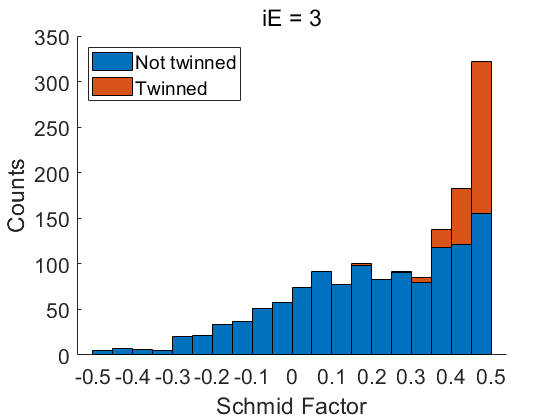

edges_sf = -0.5:0.05:0.5;
[N_t,~] = histcounts(sf_t, edges_sf);
[N_nt,~] = histcounts(sf_nt, edges_sf);
[N,~] = histcounts(sf, edges_sf);

figure; hold on;
bar(edges_sf(1:end-1) +0.025 , [N_nt(:),N_t(:)], 1, 'stacked');
legend({'Not twinned', 'Twinned'},'Location','northwest');
set(gca,'fontsize',16, 'XTick',-0.5:0.1:0.5);
xlabel('Schmid Factor');
ylabel('Counts');
title(['iE = ',num2str(iE_select)],'fontweight','normal');


% Use 'histogram' rather than 'bar' to plot
% figure; hold on;
% histogram(sf_nt,edges_sf);
% histogram(sf_t,edges_sf);
% legend({'Not-twinned', 'Twinned'},'Location','northwest');
% set(gca,'fontsize',14, 'XTick',-0.5:0.1:0.5);
% xlabel('Schmid Factor');
% ylabel('Counts');
% title(['iE = ',num2str(iE_select)],'fontweight','normal');

## (1.2) use [bar plot] for [Count of twinned and not-twinned] vs [Grain_diameter]

close all;

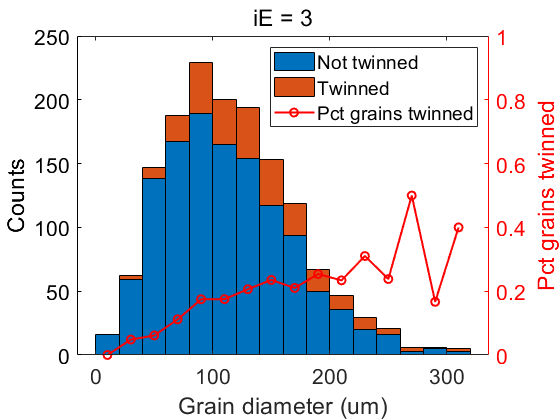

edges_gd = [0:20:20*15,400];

[N_t,~] = histcounts(gd_t, edges_gd);
[N_nt,~] = histcounts(gd_nt, edges_gd);

figure;
bar(edges_gd(1:end-1)+(edges_gd(2)-edges_gd(1))/2, [N_nt(:),N_t(:)], 1, 'stacked');

xlabel('Grain diameter (um)');
ylabel('Counts');
set(gca,'ylim',[0 250]);

yyaxis right;
set(gca,'ycolor','r')
plot(edges_gd(1:end-1)+(edges_gd(2)-edges_gd(1))/2, N_t./(N_t+N_nt),'-ro','linewidth',1.5);
ylabel('Pct grains twinned');
legend('Not twinned','Twinned','Pct grains twinned','location','northeast');
set(gca,'fontsize',16,'ylim',[0 1]);
title(['iE = ',num2str(iE_select)],'fontweight','normal');

## (1.3) Use [box plot] to show the distribution of [SF] vs. [Grian_diameter] for [twinned, and non-twinned] grains.

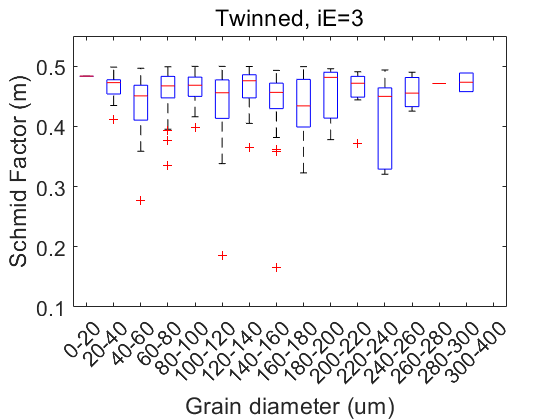

gv_t = discretize(gd_t, edges_gd);  % grouping variable: grain diameter
gv_nt = discretize(gd_nt, edges_gd);

for ii = 1:length(edges_gd)-1
    labels_gd{ii} = [num2str(edges_gd(ii)),'-',num2str(edges_gd(ii+1))];
end

figure;
Ndiff = length(edges_gd)-1 - numel(unique(gv_t));   % sometimes, a group does not have anything.  --> Note, this is wrong !!!
boxplot([sf_t;nan*ones(Ndiff,1)], [gv_t;max(gv_t)+(1:Ndiff)']);
title(['Twinned, iE=',num2str(iE)],'fontweight','normal');
xlabel('Grain diameter (um)'); ylabel('Schmid Factor (m)');
set(gca,'ylim',[0.1,0.55],'xticklabels',labels_gd,'xticklabelrotation',45,'fontsize',16);

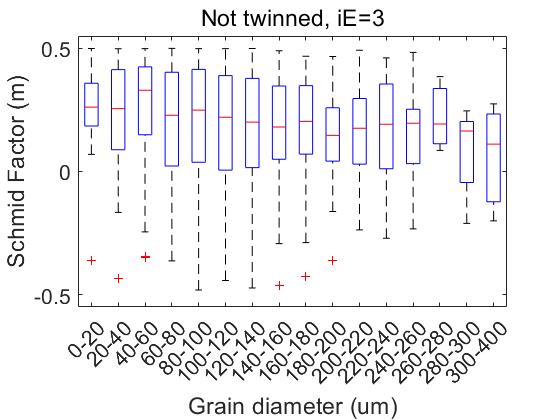


figure;
Ndiff = length(edges_gd)-1 - numel(unique(gv_nt));
boxplot([sf_nt;nan*ones(Ndiff,1)], [gv_nt;max(gv_t)+(1:Ndiff)']);
title(['Not twinned, iE=',num2str(iE)],'fontweight','normal');
xlabel('Grain diameter (um)'); ylabel('Schmid Factor (m)');
set(gca,'ylim',[-0.55,0.55],'xticklabels',labels_gd,'xticklabelrotation',45,'fontsize',16);

## (1.4) Use 2D [plot], [x=Grain_diameter] vs. [y=SF], [symbol = twinned vs. not-twinned] to show

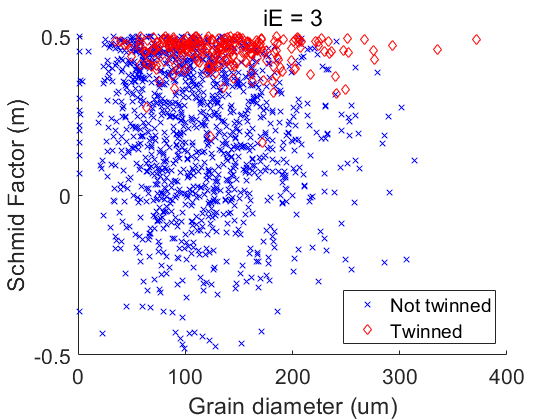

figure; hold on;
plot(gd_nt, sf_nt, 'bx');
plot(gd_t, sf_t, 'rd');
legend('Not twinned','Twinned','Location','southeast');
xlabel('Grain diameter (um)');
ylabel('Schmid Factor (m)');
set(gca,'fontsize',16);
title(['iE = ',num2str(iE_select)],'fontweight','normal');

## (1.5) Summarize the [Twin_vol_fraction] vs. [Grain_diameter] for twinned grains

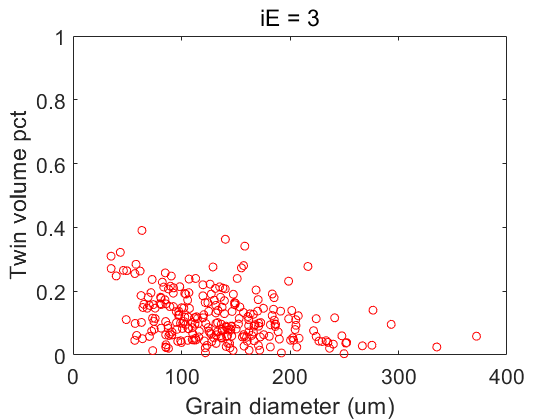

figure;
plot(gd_t,vol_t./vol_g,'or');
set(gca,'xlim',[0 400],'ylim',[0,1],'fontsize',16);
xlabel('Grain diameter (um)');
ylabel('Twin volume pct');
title(['iE = ',num2str(iE)],'fontweight','normal');

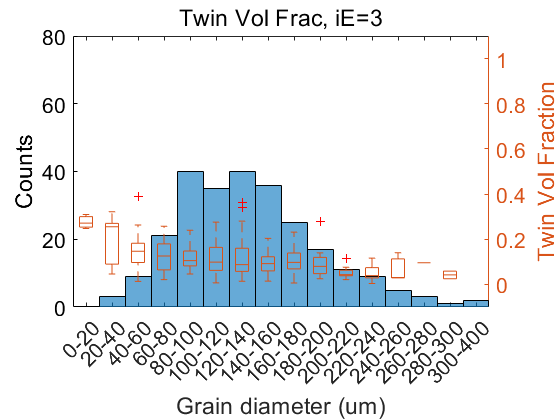


% Use [Counts] vs [grain_diameter] as backgournd, Use [box plot] to show [twin_vol_fraction] vs [grain_diameter]
figure; hold on;
edges_gd = [0:20:20*15,400];
histogram(gd_t,edges_gd);
set(gca,'ylim',[0 80]);
ylabel('Counts');

tvf = vol_t./vol_g;
gv = discretize(gd_t, edges_gd);  % grouping variable: grain diameter

yyaxis right;

for ii = 1:length(edges_gd)-1
    labels_gd{ii} = [num2str(edges_gd(ii)),'-',num2str(edges_gd(ii+1))];
end

Ndiff = length(edges_gd)-1 - numel(unique(gv));   % sometimes, a group does not have anything
boxplot([tvf;nan*ones(Ndiff,1)], [gv;max(gv)+(1:Ndiff)'],'positions', 10:20:20*16, 'colors',[0.8500    0.3250    0.0980]);
title(['Twin Vol Frac, iE=',num2str(iE)],'fontweight','normal');
xlabel('Grain diameter (um)'); ylabel('Twin Vol Fraction');
set(gca,'ylim',[-0.1, 1.1],'xticklabels',labels_gd,'xticklabelrotation',45,'fontsize',16);

## (1.6) And as it should be, use [boxplot] and [plot] to show the distribution of [SF] vs. [Grain_diameter] for all grains shows quite uniform distribution

close all;

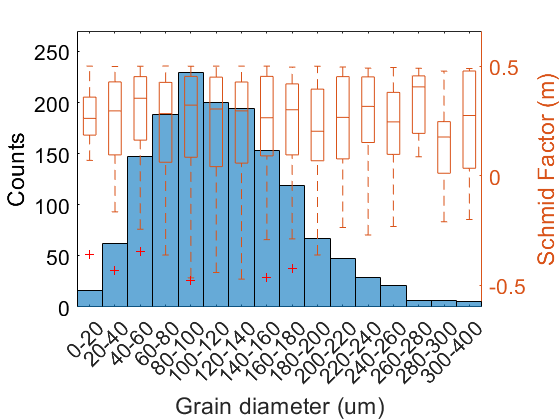

figure; hold on;
edges_gd = [0:20:20*15,400];
histogram(gd,edges_gd);
set(gca,'ylim',[0 270]);
% set(gca,'ylim',[0 500],'YTick',[0:50:250]);
ylabel('Counts');

gv_gd = discretize(gd, edges_gd);

yyaxis right;
boxplot(sf_max, gv_gd, 'positions', 10:20:20*16, 'colors',[0.8500    0.3250    0.0980]);
set(gca,'fontsize',14);
for ii = 1:length(edges_gd)-1
    labels_gd{ii} = [num2str(edges_gd(ii)),'-',num2str(edges_gd(ii+1))];
end
set(gca,'xticklabels',labels_gd,'xticklabelrotation',45,'ylim',[-0.6, 0.66]);
% set(gca,'ylim',[-1.5,0.6],'YTick',[-0.5:0.25:0.5]);
ylabel('Schmid Factor (m)');
xlabel('Grain diameter (um)');

set(gca,'fontsize',16,'TickLength', [0.005, 1]);


% And if plot on IPF
% for ii = unique(label_gd)
%     plot_on_IPF(eulers(label_gd==ii,:),[0 0 0],[0 0 0],[1 0 0],19:24,[-1 0 0; 0 0 0; 0 0 0],'Mg','Twin');
%     title([labels_gd{ii},'um']);
% end

## (2) Illustrate the determined twin GB and intersection

on exx map grain boundary --> white twin boundary --> black twin point --> o red

if 0
    iE_select = 2;
    
    close all;
    % ind = (tb_iE==iE_select);   % (option-1) At this strain level
    ind = (tb_iE<=iE_select);   % (option-2) Accumulatively
    
    gbNum = tb_gbNum(ind);      % gbNum for twin grain boundaries
    pts = tb_pts(ind);
    pts = cell2mat(pts(:));     % all intersecting points found
    
    tMap = trueTwinMapCell{iE_select};
    gbMap = grow_boundary(grow_boundary(uniqueBoundary>0));
    tgbMap = ismember(uniqueBoundary,gbNum);
    tgbMap2 = tBoundary_accum{iE_select};
    t = zeros(size(tgbMap));
    t(tgbMap==1) = 1;
    tgbMap = t;
    
    tgb_X = X(find(tgbMap));
    tgb_Y = Y(find(tgbMap));
    % tgbMap = grow_boundary(grow_boundary(grow_boundary(tgbMap)));
    
    map = strainFile{iE_select}.exx;
    myplot(map);limit = caxis; close;   % get default limit for the strain map
    
    map(gbMap==1) = inf;    % make GB white
    myplot(X, Y, map, grow_boundary(grow_boundary(tgbMap)));
    hold on;
    
    plot(tgb_X,tgb_Y,'.k','markersize',4);  % twin gb point
    plot(pts(:,1),pts(:,2),'.r','markersize',8);  % twin intersection point
    
    caxis(limit); title('')
    
end
% % (alt method)
% map = strainFile{iE_select}.exx;
% myplot(map);limit = caxis; close;   % get default limit for the strain map
%
% map(tMap>0) = 1;    % twin area = 1
% map(gbMap==1) = -1;  % grain boundary
% map(tgbMap==1) = 2;     % twin boundary
%
% myplotm(map,'x',X,'y',Y,'r',2);
% colormapA(gray);
% hold on;
% plot(tgb_X,tgb_Y,'.r','markersize',4);  % twin gb point
% plot(pts(:,1),pts(:,2),'o','markersize',4,'MarkerFaceColor',[0 1 0],'MarkerEdgeColor','none');  % twin intersection point
%
% % maximize and adjust
% ca(limit); title('')
% print([num2str(iE_select),'_myfile.tiff'],'-r1200','-dtiff')